## Successione di funzioni convergenti

**Convergenza puntuale**

Definisco il dominio

f_int=[0,1]

f_int =      0     1


t_int=[-1,1.5]

t_int =    -1.0000    1.5000


Definisco implicitamente la funzione limite

f_lim= @(x) (x < 1) * 0 + (x == 1) * 1

f_lim = function_handle with value:
    @(x)(x<1)*0+(x==1)*1


Costruisco un intorno della funzione che sarà evidenziato

epsilon=0.1

epsilon = 0.1000

f_up=@(x) (x < 1) * 0 + (x == 1) * 1+epsilon

f_up = function_handle with value:
    @(x)(x<1)*0+(x==1)*1+epsilon


f_lo=@(x) (x < 1) * 0 + (x == 1) * 1

f_lo = function_handle with value:
    @(x)(x<1)*0+(x==1)*1


Definisco i valori di n in un vettore

n_val=[1, 5, 10, 25, 50]

n_val =      1     5    10    25    50


Apro l'ambiente figure

figure
hold on
grid on

Definisco una funzione per i colori

colors=flipud(autumn(length(n_val)))

colors =     1.0000    1.0000         0
    1.0000    0.7500         0
    1.0000    0.5000         0
    1.0000    0.2500         0
    1.0000         0         0


Definisco e disegno la successione

for idx=1:length(n_val)
    n= n_val(idx)
    fn=@(x) x.^n
    fplot(fn,f_int, LineWidth=1.7, DisplayName=['f_{' num2str(n) '}(x)'], Color=colors(idx,:))
end

n = 1

fn = function_handle with value:
    @(x)x.^n


n = 5

fn = function_handle with value:
    @(x)x.^n


n = 10

fn = function_handle with value:
    @(x)x.^n


n = 25

fn = function_handle with value:
    @(x)x.^n


n = 50

fn = function_handle with value:
    @(x)x.^n


Disegno la funzione limite e il tubo

fplot(f_lim, f_int, 'k', 'LineWidth', 1.5, 'DisplayName', 'f(x) = |x|')
fplot(f_up, t_int, 'Color',  [0.4940 0.1840 0.5560] , 'LineWidth', 1, 'LineStyle','--', HandleVisibility='off')
fplot(f_lo, t_int, 'Color', [0.4940 0.1840 0.5560], 'LineWidth', 1, 'LineStyle','--',HandleVisibility='off')

Rifinisco gli ultimi dettagli

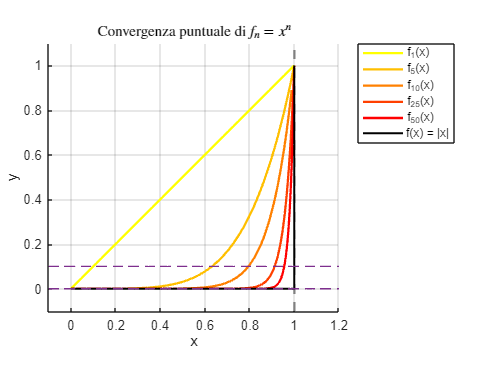

axis equal
legend('Location','bestoutside')
xlabel('x')
ylabel('y')
xlim([-0.1 1.2])
ylim([-0.1 1.1])
title("Convergenza puntuale di $f_n=x^n$", "Interpreter","latex")
hold off

**Convergenza uniforme**

Definisco l'intervallo

f_int=[-1, 1]

f_int =     -1     1


Definisco implicitamente la funzione limite. Per fare ciò, uso @, indico nelle prime tonde gli argomenti della funzione e dopo la legge della funzione.

f_lim=@(x) abs(x) 

f_lim = function_handle with value:
    @(x)abs(x)


Costruisco un intorno della funzione che sarà evidenziato

f_up=@(x) abs(x)+epsilon

f_up = function_handle with value:
    @(x)abs(x)+epsilon


f_lo=@(x) abs(x)-epsilon

f_lo = function_handle with value:
    @(x)abs(x)-epsilon


Definisco i valori di n in un vettore

n_val=[1, 2, 5, 7, 20] 

n_val =      1     2     5     7    20


Apro l'ambiente figure

figure
hold on
grid on

Definisco e disegno la successione

for idx=1:length(n_val)
    n= n_val(idx)
    fn=@(x) (1/n)*sqrt(1+n^2*x.^2)
    fplot(fn,f_int, LineWidth=1.7, DisplayName=['f_{' num2str(n) '}(x)'], Color=colors(idx,:))
end

n = 1

fn = function_handle with value:
    @(x)(1/n)*sqrt(1+n^2*x.^2)


n = 2

fn = function_handle with value:
    @(x)(1/n)*sqrt(1+n^2*x.^2)


n = 5

fn = function_handle with value:
    @(x)(1/n)*sqrt(1+n^2*x.^2)


n = 7

fn = function_handle with value:
    @(x)(1/n)*sqrt(1+n^2*x.^2)


n = 20

fn = function_handle with value:
    @(x)(1/n)*sqrt(1+n^2*x.^2)


Disegno la funzione limite e il tubo

fplot(f_lim, f_int, 'k', 'LineWidth', 1.5, 'DisplayName', 'f(x) = |x|')
fplot(f_up, f_int, 'Color',  [0.4940 0.1840 0.5560] , 'LineWidth', 1, 'LineStyle','--', HandleVisibility='off')
fplot(f_lo, f_int, 'Color', [0.4940 0.1840 0.5560], 'LineWidth', 1, 'LineStyle','--',HandleVisibility='off')

Rifinisco gli ultimi dettagli

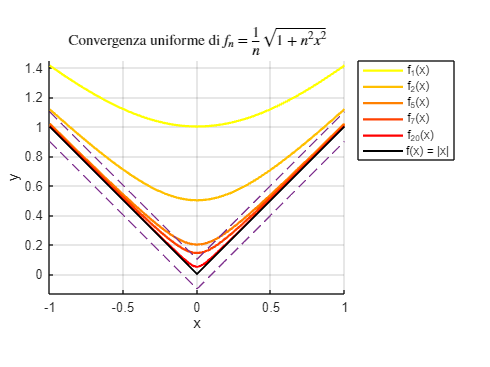

axis equal
legend('Location','bestoutside')
xlabel('x')
ylabel('y')
title("Convergenza uniforme di $f_n=\frac{1}{n} \sqrt{1+n^2x^2}$", Interpreter="latex")